# Detecting Abnormal EEG Signals with Deep Learning

This example shows how you can use deep learning techniques to build a model that classifies signal data. We will preprocess and represent signal data as images to be used with a convolutional neural net (CNN). The CNN will be trained end-to-end to classify normal and abnormal electroencephalography (EEG) data from a public dataset [1].

clear; close all; clc;
rng('default'); % ensure repeatability of training and test data set splits

## **Introduction**

EEG is a non-invasive, electrophysiological monitoring method to record the electrical activity of a person's brain over a period of time. Determining whether a patient's EEG is normal or abnormal can serve as a screening method for neurological disorders.

The EEG dataset used in this example was obtained from the Temple University Hospital (TUH) EEG Abnormal Corpus. The recordings are accessible as European Data Format (EDF) files [2]. Researchers assigned labels of *abnormal* or *normal *to signals based on agreement among surveyed neurologists. This dataset is available for exploration and download via [TUH EEG resources](https://www.isip.piconepress.com/projects/tuh_eeg/html/downloads.shtml).

This example uses a deep CNN trained from end-to-end on the raw EEG signals after minimal pre-processing. CNNs are particularly useful for detecting complex patterns and exploiting hierarchical structures in images by using convolutions. Although EEG signals are not images but rather dynamic time series from electrode measurements, this example uses a deep CNN architecture that allows EEG signal input to be represented as a 2D-array.

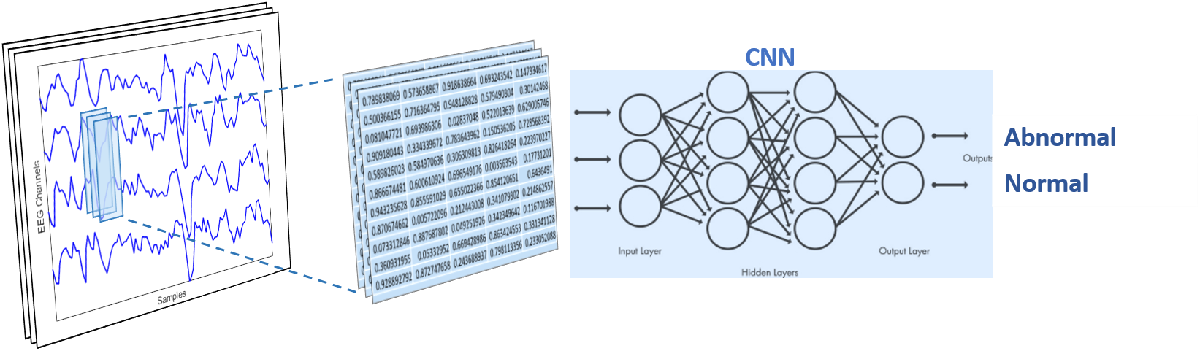

## Configure

Select the checkbox if you'd like to perform the training live:

doTraining = true;

Training from scratch requires many parameters for network and training and options. `initializeParameters` initializes pre-configured parameter values. For further investigation and learning, try modifying values in `param` to see how network training and performance is affected. 

param = initializeParameters();

The number of minutes of each recording used for training drastically affects training time. Using a larger number of minutes of each recording will will cause training to take hours to complete. `param.total_recording_mins` determines how many minutes of data from each file is used for training. `param.iter_recording_mins` determines how many minutes the network trains on during a single training iteration:

param.total_recording_mins = 16;
param.iter_recording_mins = 1;

Point to the folder containing signal data:

dataFolder = 'edf';

In our analysis, we found some of the data to be incompatible with our training workflow. These files were identified and their names were stored in a MAT-file:

load excludeFileList

## **I. Prepare Signal Data**

This dataset has already been split into a training and evaluation set, with the data for each stored in "train" and "eval" directories, respectively. Overall, it contains EEG recordings obtained from 2,130 study participants clinically classified as pathological or normal. The EDF file data includes clinical data comprising EEG recordings acquired for around 20 minutes from at least 21 standard electrode positions.

### Modify Data Headers

trainAndTestFiles = dir(fullfile(dataFolder,'**','*.edf'));
trainAndTestFiles = fullfile({trainAndTestFiles.folder},{trainAndTestFiles.name});
trainAndTestFiles = trainAndTestFiles(~contains(trainAndTestFiles,excludeFileList));

cellfun(@modifyHeader,trainAndTestFiles);

### Explore Training Data

Separate normal and abnormal files in the training dataset.

normalTrainFiles = trainAndTestFiles(contains(trainAndTestFiles,fullfile(filesep,'train','normal')));
abnormalTrainFiles = trainAndTestFiles(contains(trainAndTestFiles,fullfile(filesep,'train','abnormal')));

Randomly select a normal and abnormal training file.

normalTrainFile = normalTrainFiles{randi([1 numel(normalTrainFiles)])};
abnormalTrainFile = abnormalTrainFiles{randi([1 numel(abnormalTrainFiles)])};

You can use the EDF File Analyzer App to visualize these signals by opening the app from the Apps tab or by running `edfFileAnalyzer`, with either `normalTrainFile` or `abnormalTrainFile` as an argument.

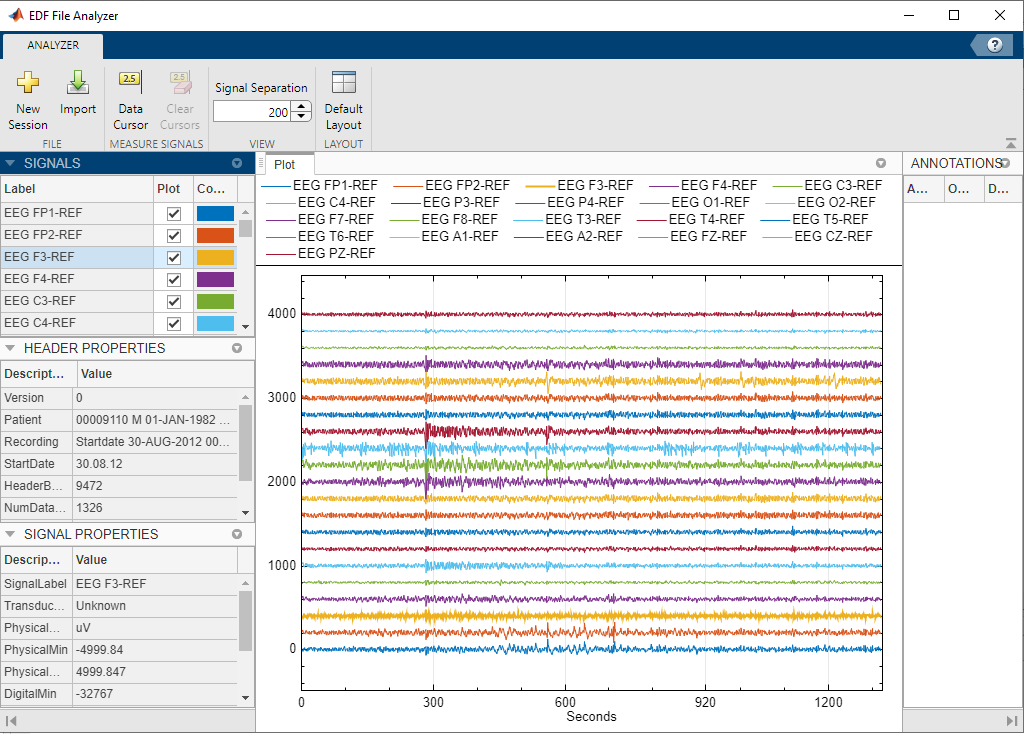

An [`edfinfo`](https://www.mathworks.com/help/signal/ref/edfinfo.html) object stores information about an EDF file.

trainFileInfo = edfinfo(normalTrainFile)

trainFileInfo =   edfinfo with properties:

              Filename: "00009926_s001_t001.edf"
           FileModDate: "08-Jan-2021 15:20:44"
              FileSize: 18335578
               Version: "0"
               Patient: "00009926 M 01-JAN-1969 00009926 Age:44"
             Recording: "Startdate 22-APR-2013 00009926_s001 00 X"
             StartDate: "22.04.13"
             StartTime: "11.30.24"
           HeaderBytes: 7936
              Reserved: "EDF+C"
        NumDataRecords: 1357
    DataRecordDuration: 1 sec
            NumSignals: 30
          SignalLabels: [30×1 string]
       TransducerTypes: [30×1 string]
    PhysicalDimensions: [30×1 string]
           PhysicalMin: [30×1 double]
           PhysicalMax: [30×1 double]
            DigitalMin: [30×1 double]
            DigitalMax: [30×1 double]
             Prefilter: [30×1 string]
            NumSamples: [30×1 double]
        SignalReserved: [30×1 string]
      

We will use a subset of the `SignalLabels` in `trainFileInfo`, which correspond to electrodes used to obtain the signal data.

electrodesToMatch = {'A1', 'A2', 'C3', 'C4', 'CZ', 'F3', 'F4',...
'F7', 'F8','FP1', 'FP2', 'FZ', 'O1', 'O2',...
'P3', 'P4', 'PZ', 'T3','T4', 'T5', 'T6'};
extraLabelWords = {'EEG ','REF','LE','-'};
electrodesToKeep = trainFileInfo.SignalLabels(matches(erase(trainFileInfo.SignalLabels,extraLabelWords),electrodesToMatch));

[`edfread`](https://www.mathworks.com/help/signal/ref/edfread.html) reads the data from an EDF file into a timetable. We can specify which electrode channels and how many records of the data to read.

edfread(normalTrainFile,"SelectedSignals",electrodesToKeep,...
                           "SelectedDataRecords",(61:(param.total_recording_mins+1)*60))

ans = 960×21 timetable
    Record Time      EEGFP1_REF        EEGFP2_REF        EEGF3_REF         EEGF4_REF         EEGC3_REF         EEGC4_REF         EEGP3_REF         EEGP4_REF         EEGO1_REF         EEGO2_REF         EEGF7_REF         EEGF8_REF         EEGT3_REF         EEGT4_REF         EEGT5_REF         EEGT6_REF         EEGA1_REF         EEGA2_REF         EEGFZ_REF         EEGCZ_REF         EEGPZ_REF   
    ___________    ______________    ______________    ______________    ______________    ______________  

We use the helper function `customRead` to apply `edfread` and `edfinfo` to a given EDF file. It will return a 2D array representing an unraveled version of the table shown above, and a struct containing the sampling frequency and filename.

customReadFcn{1} = @(filename)edfread(filename,"SelectedSignals",electrodesToKeep,...
                                      "SelectedDataRecords",(61:(param.total_recording_mins+1)*60));
customReadFcn{2} = @(filename)edfinfo(filename).NumSamples(1)/seconds(edfinfo(filename).DataRecordDuration);

[normalTrainData,normalTrainInfo] = customRead(normalTrainFile, customReadFcn);
[abnormalTrainData,abnormalTrainInfo] = customRead(abnormalTrainFile, customReadFcn);

The helper function `processData` reduces the effect of strong artifacts and resamples the data at 100 Hz to speed up computations during training. It returns a cell array with a 2D array containing preprocessed recordings from a subset of electrodes and a label for the entire file  (0 - normal, 1 - abnormal).

normalTrainData = processData(normalTrainData,normalTrainInfo,param)

normalTrainData = 1×2 cell array
    {96000×21 double}    {[0]}


abnormalTrainData = processData(abnormalTrainData,abnormalTrainInfo,param)

abnormalTrainData = 1×2 cell array
    {96000×21 double}    {[1]}


Plot samples from normal and abnormal recordings in a [`stackedplot`](https://www.mathworks.com/help/matlab/ref/stackedplot.html). The electrode whose recordings are displayed and record are randomly chosen.

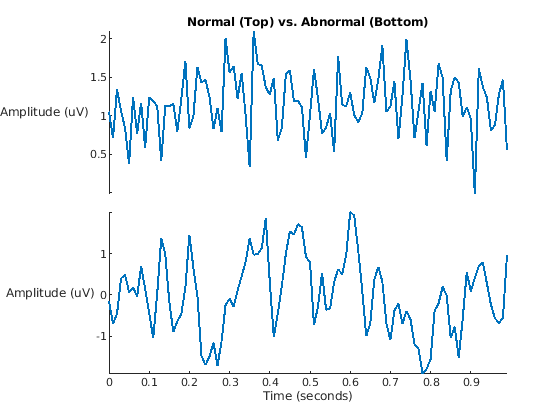

electrode = randi([1 21]);
recording = randi([1 height(normalTrainData{1})/param.desiredFs]);
t = (0:100-1)'/param.desiredFs;
Y = [normalTrainData{1}((recording-1)*param.desiredFs+1:recording*param.desiredFs,electrode),...
     abnormalTrainData{1}((recording-1)*param.desiredFs+1:recording*param.desiredFs,electrode)];
stackedplot(t,Y,"Title",'Normal (Top) vs. Abnormal (Bottom)',...
           "DisplayLabels",{'Amplitude (uV)','Amplitude (uV)'},...
           "XLabel",'Time (seconds)',"LineWidth",1.5) 

Notice that it may be challenging to visually discern the EEG signal characteristics that distinguish a normal EEG from an abnormal EEG. To convince yourself of this, try running this section a few times by clicking the 'Run' button below. 

### Store the Data

A [`signalDatastore`](https://www.mathworks.com/help/signal/ref/signaldatastore.html) object conveniently stores and manages our collection of EDF files. By defining `customRead` as the datastore's read function, we can use `readall` to read all of the data for the files in one pass. In addition, instead of transforming individual files after reading them into memory, we can use `transform` to form a data processing pipeline with our helper function(s).

numTrainFiles = nnz(contains(trainAndTestFiles,"train"));
trainDatastore = signalDatastore(trainAndTestFiles(contains(trainAndTestFiles,"train")),...
                                "ReadFcn",@(f)customRead(f,customReadFcn),'FileExtensions','.edf');
trainDatastore = transform(trainDatastore,@(data,info) processData(data,info,param), "IncludeInfo",true);
trainDatastore = shuffle(trainDatastore);

## **II. Prepare Network and Perform Deep Learning**

### **Define the Architecture**

This example uses a deep CNN architecture that allows EEG signal input to be represented as a 2D-array with the number of electrode channels as the height and the number of time steps as the width. The deep CNN architecture is constructed using parameters and layers specified in [3]. Since we are training a new CNN from scratch, it will take longer than starting with a pretrained network and fine-tuning it with transfer learning. 

We must first specify which layers it will contain and in what order. The local helper function `constructNetwork` builds a deep CNN using network parameters and training options stored in `param`.

All of the layers used in this example other than `identityLayer` are found in the [MATLAB Deep Learning Toolbox](https://www.mathworks.com/products/deep-learning.html). Use [`analyzeNetwork`](https://www.mathworks.com/help/deeplearning/ref/analyzenetwork.html) to visualize and understand the architecture of a network, check that you have defined the architecture correctly, and detect problems before training

layers = constructNetwork(param);
analyzeNetwork(layers)

There are a large number of options for training classifiers. Many times, default options can be used, but we specify a few training options here that will help boost classifier accuracy.

options = trainingOptions('adam', ... %  use the adaptive moment estimation solver to optimize deep CNN parameters
    'MaxEpochs',param.max_epoch,... % allow the network to make 35 passes through the dat
    'InitialLearnRate',param.init_lr, ... % sets 0.001 as the default learning rate
    'MiniBatchSize',param.mini_batch_size, ... % directs the network to look at 64 training signals at a time
    'Shuffle','every-epoch', ... 
    'Plots','training-progress', ... % generate plots that show a graphic of the training progress
    'Verbose',false,... % suppress the table output that corresponds to the data shown in plots
    'ExecutionEnvironment','auto',... % use a GPU if one is available
    'OutputFcn',@(info)stopCriteria(info,param.val_patience)); % stop training if validation accuracy fails to increase for 6 epochs

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


Elapsed time is 978.799517 seconds.


### Train the Network

The Deep CNN is trained by iterating through `param.iter_recording_mins` minute intervals in the data, for `param.total_recording_mins `minutes. Using `resizeData` on a `param.iter_recording_mins` minute interval for a single EDF file returns: 

(1) a 4D array, whose 1st dimension is the number of electrode channels, 2nd dimension is the number of data samples, and 3rd and 4th dimensions are singleton dimensions. 

(2) a label for the file.

Using `resizeData` on the entire dataset results in a two-column cell array. The first column contains a 4D array for each training file and the second column contains a label for each training file. Before training, the first column is concatenated along the 4th dimension and the second column is concatenated along the 1st dimension. A subset of the training data is used as validation data and is specified in `options` as such.

Train the Deep CNN with the specified training options and layer architecture by using [`trainNetwork`](https://www.mathworks.com/help/deeplearning/ref/trainnetwork.html). Because the training set is large, the training process will take several minutes or hours, depending on the number of minutes of signal data used for training. This option was specified in the **Configure** section.

if doTraining
    numTrainIters = floor(param.total_recording_mins/param.iter_recording_mins);
    
    for iterNum = 1:numTrainIters
        
        trainDatastore_ = transform(trainDatastore, @(x) resizeData(x,iterNum,param));
    
        datastoreData = readall(trainDatastore_,'UseParallel',true);
        
        [trainInd, valInd, ~] = dividerand(numTrainFiles,0.75,0.25,0);
        trainData = datastoreData(trainInd,:);
        valData = datastoreData(valInd,:);
        clear datastoreData
        
        trainData = {cat(4,trainData{:,1}), cat(1,trainData{:,2})};
        valData = {cat(4,valData{:,1}), cat(1,valData{:,2})};

        options.ValidationData = valData;
        net = trainNetwork(trainData{:,1}, trainData{:,2},layers,options);
        layers = net.Layers;
        
        clear trainDatastore_
        clear trainData
        clear valData
        delete(findall(0));   
    end
else
    load eegNet
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


## Evaluate the Trained Model

Determine how many minutes of each recording to use for testing:

param.total_recording_mins = 16;

Calculate the testing accuracy, which represents the accuracy of the classifier on the testing dataset. If `param.iter_recording_mins `is less than `param.total_recording_mins`, we will calculate the trial-wise accuracy by taking the mode of the predicted labels for any given testing file.

numTestFiles = nnz(contains(trainAndTestFiles,"eval"));
testDatastore = signalDatastore(trainAndTestFiles(contains(trainAndTestFiles,"eval")),...
                                "ReadFcn",@(f)customRead(f,customReadFcn),'FileExtensions','.edf');
testDatastore = transform(testDatastore,@(data,info) processData(data,info,param), "IncludeInfo",true);

Initialize `predictedLabels` and `actualLabels` as `<undefined>` categorical arrays to store the predicted label and actual label, respectively, for each testing file.

numTestIters = floor(param.total_recording_mins/param.iter_recording_mins);
predictedLabels = categorical(repmat({''},numTestIters,numTestFiles),{'abnormal' 'normal'});
actualLabels = categorical(repmat({''},numTestIters,numTestFiles),{'abnormal' 'normal'});

Predict the labels for every `param.iter_recording_mins` minute interval in the test data, for `param.total_recording_mins `minutes.

for iterNum = 1:numTestIters
    testDs_ = transform(testDatastore, @(x) resizeData(x,iterNum,param));
    testData = readall(testDs_,'UseParallel',true);
    predictedLabels(iterNum,:) = classify(net, cat(4,testData{:,1}))';
    actualLabels(iterNum,:) = cat(1,testData{:,2})';
end

Calculate the mode of `preds,` if needed, to get an array of classifer predictions for each testing file.

if height(actualLabels)>1
    actualLabels = mode(actualLabels);
    predictedLabels = mode(predictedLabels);
end
finalAccuracy = 100*nnz(actualLabels == predictedLabels)/width(predictedLabels);

In classification problems, confusion matrices are used to visualize the performance of a classifier on a set of data for which the true values are known. The Target Class is the ground-truth label of the signal, and the Output Class is the label assigned to the signal by the network. The axes labels represent the class labels, normal and abnormal.

Use the [`confusionchart`](https://www.mathworks.com/help/deeplearning/ref/confusionchart.html) command to calculate the overall classification accuracy for the testing data predictions. Specify 'RowSummary' as 'row-normalized' to display the true positive rates and false positive rates in the row summary. Also, specify 'ColumnSummary' as 'column-normalized' to display the positive predictive values and false discovery rates in the column summary.

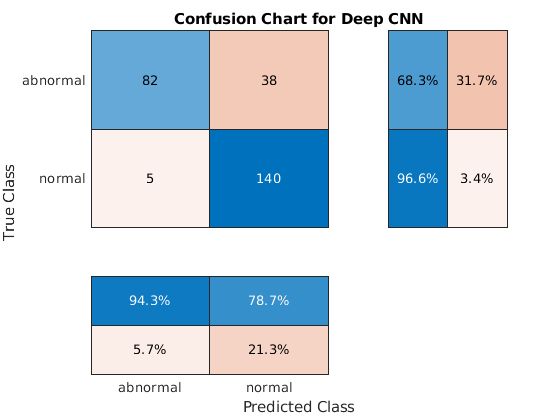

confusionchart(actualLabels,predictedLabels,...
                    'RowSummary','row-normalized',...
                    'ColumnSummary','column-normalized', ...
                    'Title','Confusion Chart for Deep CNN');

fprintf('Trialwise accuracy on the test set is %0.2f%%\n',finalAccuracy);

Trialwise accuracy on the test set is 83.77%


## References

[1] Obeid, I., & Picone, J. (2018). The Temple University Hospital EEG Data Corpus. In Augmentation of Brain Function: Facts, Fiction and Controversy. Volume I: Brain-Machine Interfaces (1st ed., pp. 394-398). Lausanne, Switzerland: Frontiers Media S.A.

[2] Kemp, Bob, Alpo Värri, Agostinho C. Rosa, Kim D. Nielsen, and John Gade. “A Simple Format for Exchange of Digitized Polygraphic Recordings.” Electroencephalography and Clinical Neurophysiology 82, no. 5 (May 1992): 391–93. https://doi.org/10.1016/0013-4694(92)90009-7.

[3] R. Schirrmeister, L. Gemein, K. Eggensperger, F. Hutter and T. Ball, "Deep learning with convolutional neural networks for decoding and visualization of EEG pathology," 2017 IEEE Signal Processing in Medicine and Biology Symposium (SPMB), Philadelphia, PA, 2017

[4] R. T. Schirrmeister, J. T. Springenberg, L. D. J. Fiederer, M. Glasstetter, K. Eggensperger, M. Tangermann, F. Hutter, W. Burgard, and T. Ball, “Deep learning with convolutional neural networks for EEG decoding and visualization,” Human Brain Mapping, Aug. 2017.

## Helper Functions

function modifyHeader(filename)
    fid = fopen(filename,'r+');
    fseek(fid,192,'bof');
    fwrite(fid,'EDF+C');
    fclose(fid);
end

function [data,info] = customRead(filename, customReadFcn)
    data = cell2mat(table2cell(customReadFcn{1}(filename)));
    info.SampleRate = customReadFcn{2}(filename);
    info.FileName = filename;
end

function [dataOut,infoOut] = processData(dsData,dsInfo,params)
    record = dsData;
    %convert data to uV
    %record = record * 1e6;
    %Clip the amplitude values to the range of +/- 800uV to reduce the
    %effects of strong artifacts
    record(record>params.max_abs_val) = params.max_abs_val;
    record(record<-params.max_abs_val) = -params.max_abs_val;
    %Remove the first minute of each recording as it contains stronger
    %artifacts
    %The paper divided the data by a factor of 10
    record = record/10;
    %Resample the data to 100Hz to speed up the computation
    [p,q] = rat(params.desiredFs / dsInfo.SampleRate);
    record = resample(record,p,q);
    dataOut = [{record},{contains(dsInfo.FileName,'abnormal')}];
    infoOut = {' '};
end

function outputCell = resizeData(inputCell,iter,params)
    sig = inputCell{1}';
    lab = inputCell{2};
    block = zeros(params.n_chans,params.targetLength,1,1);
    block(:,:,:,1) = sig(:,floor((iter-1)*params.iter_recording_mins*60*params.desiredFs+1):floor(iter*params.iter_recording_mins*60*params.desiredFs));
    outputCell = {block,categorical(lab,[0 1],{'normal' 'abnormal'})};
end

function netLayers = constructNetwork(params)
    inputSize = [params.n_chans,params.targetLength];
    netLayers = [
        imageInputLayer(inputSize,'Normalization','none','Name','input')
        convolution2dLayer([1 params.filter_time_length], params.n_filters_time,'Stride',[1 1],'Name','conv1')
        convolution2dLayer([params.n_chans 1], params.n_filters_spat,'Stride',[1 params.conv_stride],'Name','conv1_2')
        batchNormalizationLayer('Name','batch1')
        eluLayer('Name','elu1')
        maxPooling2dLayer([1 params.pool_time_length],'Stride',[1 params.pool_stride],'Name','pool1')
        identityLayer('elu2') 
        dropoutLayer(params.drop_prob,'Name','drop1')
        convolution2dLayer([1 params.filter_length_2],params.n_filters_2,'Stride',[1 params.conv_stride],'Name','conv2')
        batchNormalizationLayer('Name','batch2')
        eluLayer('Name','elu3')
        maxPooling2dLayer([1 params.pool_time_length],'Stride',[1 params.pool_stride],'Name','pool2')
        identityLayer('elu4') 
        dropoutLayer(params.drop_prob,'Name','drop2')
        convolution2dLayer([1 params.filter_length_3],params.n_filters_3,'Stride',[1 params.conv_stride],'Name','conv3')
        batchNormalizationLayer('Name','batch3')
        eluLayer('Name','elu5')
        maxPooling2dLayer([1 params.pool_time_length],'Stride',[1 params.pool_stride],'Name','pool3')
        identityLayer('elu6')  
        dropoutLayer(params.drop_prob,'Name','drop3')
        convolution2dLayer([1 params.filter_length_4],params.n_filters_4,'Stride',[1 params.conv_stride],'Name','conv4')
        batchNormalizationLayer('Name','batch4')
        eluLayer('Name','elu7')
        maxPooling2dLayer([1 params.pool_time_length],'Stride',[1 params.pool_stride],'Name','pool4')
        identityLayer('elu8') 
        convolution2dLayer([1 params.final_conv_length],params.n_classes,'Name','conv5')
        softmaxLayer('Name','softmax')
        classificationLayer('Name','classification')];
end

function stop = stopCriteria(info,N)
    stop = false;
    persistent bestValAccuracy
    persistent valLag
    persistent currentEpoch
    
    if info.State == "start" 
        bestValAccuracy = 0;
        valLag = 0;
        currentEpoch = info.Epoch;
    
    elseif ~isempty(info.ValidationLoss) && currentEpoch ~= info.Epoch
        currentEpoch = info.Epoch;
        if info.ValidationAccuracy > bestValAccuracy
            valLag = 0;
            bestValAccuracy = info.ValidationAccuracy;
        else
            valLag = valLag + 1;
        end

        if valLag >= N
            stop = true;
        end  
    end
end